# **Лабораторная работа №1**

# **Синтез и фильтрация ШПС-сигналов типа M - последовательностей и кодов Уолша - Адамара**

**Выполнил: Голев Андрей Дмитриевич, ИВТ-32.**

**Преподаватель: Лавриненко Александр Дмитриевич.**

## Задача №1

Реализовать функцию **Mfun( A, C )**, представляющий собой цифровой автомат генерации **M - последовательности, **где 

- **A** - фаза;

- **C** - характеристический многочлен последовательности.

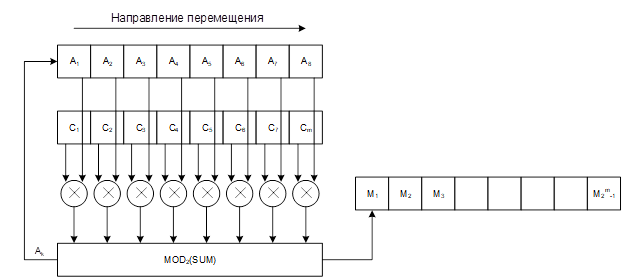

Сформировать две последовательности согласно своему варианту.

Полученные **M - последовательности **следует привести к виду [1; -1], проведя замену в исходных последовательностях:

- **0** на 1;

- **1** на -1.

clear; clc; close all;

% Вариант №6 

A   = [ 1 0 0 0 0 0 0 1 1 ];
C_1 = [ 0 0 1 1 1 0 0 1 1 1 ];
C_2 = [ 0 0 1 1 1 1 0 0 1 1 ];

M_1 = Mfun( A, C_1 );
M_2 = Mfun( A, C_2 );

M_1 = SubM(M_1);
M_2 = SubM(M_2);

Изобразить полученные М-последовательности на отдельных графиках.

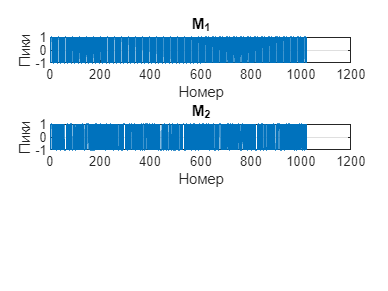

subplot( 3, 1, 1 )

plot( linspace( 1, length( M_1 ), length( M_1 ) ), M_1 )

title( "M_1" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

subplot( 3, 1, 2 )

plot( linspace( 1, length( M_2 ), length( M_2 ) ), M_2 )

title( "M_2" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

## Задача №2

Сформировать сумму M-последовательностей $M_{\textrm{сум}} =M_1 +M_2$, где $M_2$ взят со сдвигом и инверсией.

Сдвиг взять равным 100 + номер по списку в группе  * 10 <= length(M) / 2 

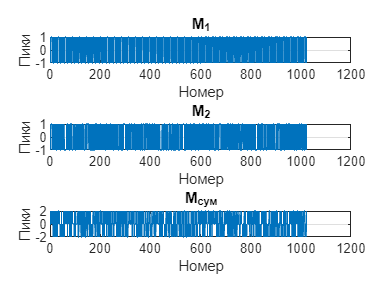

M_sum = M_1 + circshift( (M_2 * (-1) ), 160 );

subplot( 3, 1, 3 )

plot( linspace( 1, length( M_sum ), length( M_sum ) ), M_sum )

title( "M_{сум}" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

## Задача №3

Запрограммировать функцию **my_sf( A, B )**, реализующую согласованный фильтр для фильтрации **M-последовательностей** и построения **автокорреляционных** и **взаимно-корреляционных** функций, где

- **A** - сигнал

- **B** - опорная функция.

Построить **АКФ** для $M_1$.

AKF = my_sf(M_1, M_1);

figure

subplot(4,2,1)
plot( linspace( 1, length( AKF ), length( AKF ) ), AKF )

Построить **ВКФ** для $M_2$.

VKF = my_sf(M_2, M_1);

subplot(4,2,2)
plot( linspace( 1, length( VKF ), length( VKF ) ), VKF )

Из $M_{\mathrm{сум}}$ отфильтровать $M_{1\;} \ldotp$

Filtered_signal_1 = my_sf(M_sum, M_1);

subplot(4,2,3)
plot( linspace( 1, length( Filtered_signal_1 ), length( Filtered_signal_1 ) ), Filtered_signal_1 )

Из $M_{\textrm{сум}}$ отфильтровать $M_{2\;} \ldotp$

Filtered_signal_2 = my_sf(M_sum, M_2);

subplot(4,2,4)
plot( linspace( 1, length( Filtered_signal_2 ), length( Filtered_signal_2 ) ), Filtered_signal_2 )

Воспользуемся функцией xcorr

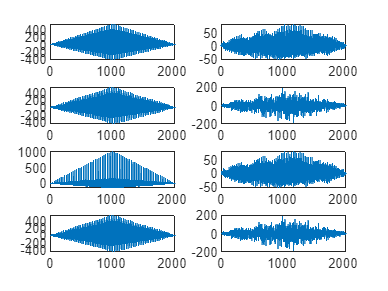

AKF = xcorr(M_1, M_1);

subplot(4,2,5)
plot( linspace( 1, length( AKF ), length( AKF ) ), AKF )

VKF = my_sf(M_2, M_1);

subplot(4,2,6)
plot( linspace( 1, length( VKF ), length( VKF ) ), VKF )

Filtered_signal_1 = my_sf(M_sum, M_1);

subplot(4,2,7)
plot( linspace( 1, length( Filtered_signal_1 ), length( Filtered_signal_1 ) ), Filtered_signal_1 )

Filtered_signal_2 = my_sf(M_sum, M_2);

subplot(4,2,8)
plot( linspace( 1, length( Filtered_signal_2 ), length( Filtered_signal_2 ) ), Filtered_signal_2 )

## Задача №4

Сформировать шум с помощью функции rand. В качестве амплитуды шума взять свой номер по списку в группе. Длина сформированного шума должна соответствовать длине M-последовательности.

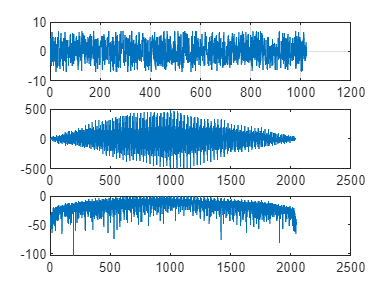

Noise = 6 - 2 * 6 * rand(1, length(M_1));

M_3 = M_1 + Noise;

figure

subplot(3,1,1)

plot( linspace( 1, length( M_3 ), length( M_3 ) ), M_3 )

grid on

Filtered_signal_3 = my_sf(M_3, M_1);

subplot(3,1,2)
plot( linspace( 1, length( Filtered_signal_3 ), length( Filtered_signal_3 ) ), Filtered_signal_3 )

dB = 20 * log10( abs( Filtered_signal_3./max( Filtered_signal_3 ) ) );

subplot(3,1,3)
plot( linspace( 1, length( dB ), length( dB ) ), dB )